close all hidden;
clearvars -except;
clc;

rng(418);                       %seed for reproducibility

## ***PROBLEM 1 (25 Pts.)***

## 1.1 Data generation

Tsampling = 0.01;      
Tfinal = 40;            
t = 0:Tsampling:(Tfinal - Tsampling);     %to produce exactly N=4000 samples
N = numel(t);

Tzero = 2;                                % 2 seconds zero input (segmentation for bias estimation)
Nz = round(Tzero / Tsampling);            % number of zero samples

### PRBS input

dwell = 0.2;
L = round(dwell / Tsampling);
nLev = ceil((N - Nz) / L);                %PRBS only after zero segment

%first producing levels
lev = zeros(nLev, 1);
for k = 1:nLev
    if rand > 0.5
        lev(k) = 1;
    else
        lev(k) = -1;
    end
end

%then dwelling them for the input
u_prbs = zeros(N - Nz, 1);                    
idx = 1;                                       
for k = 1:nLev
    for j = 1:L
        if idx > (N - Nz)                     
            break;
        end
        u_prbs(idx) = lev(k);                  
        idx = idx + 1;
    end
end

u = [zeros(Nz,1); u_prbs];                 % zero input + PRBS
u_t = u;                                   % ZOH-held input

### Plant & Sensor

s  = tf('s');                                                  
Gp = 5/(s^2 + 1.2*s + 5);                                      %plant transfer function
Gs = 1/(0.15*s + 1);                                           %sensor dynamics
y_plant = lsim(Gp, u, t, 'zoh');                               %defining "zoh" at lsim for both plant and the sensor
y_sens  = lsim(Gs, y_plant, t, 'zoh');

### Bias, noise, spikes

bias  = -0.25;                                                  %sensor bias
sigma = 0.05;                                                   %zero-mean gaussian for measurement noise
y_raw = y_sens + bias + sigma*randn(size(y_sens));                                                   
idx_spike = randsample((Nz+2):(N-1), 25);                       %spikes only in PRBS region       
y_raw(idx_spike) = y_raw(idx_spike) + 0.5 * sign(randn(numel(idx_spike), 1));    %adding twenty five 0.5 magnitude spikes

### Plots

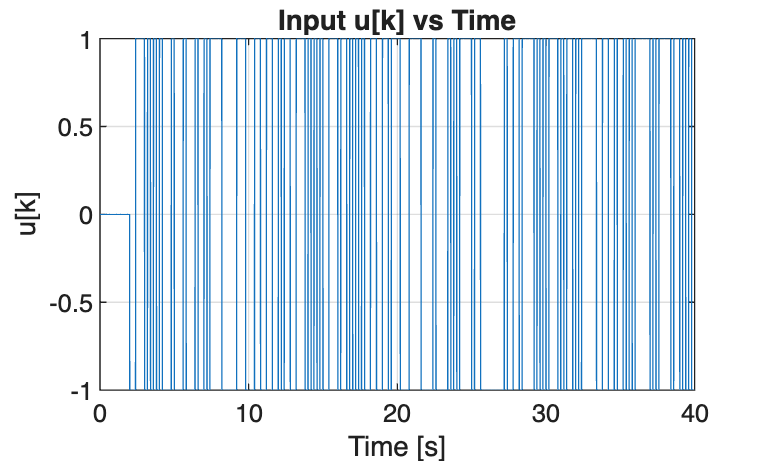

figure;
plot(t, u); grid on; xlabel('Time [s]'); ylabel('u[k]');    %u[k] input plotting
title('Input u[k] vs Time');

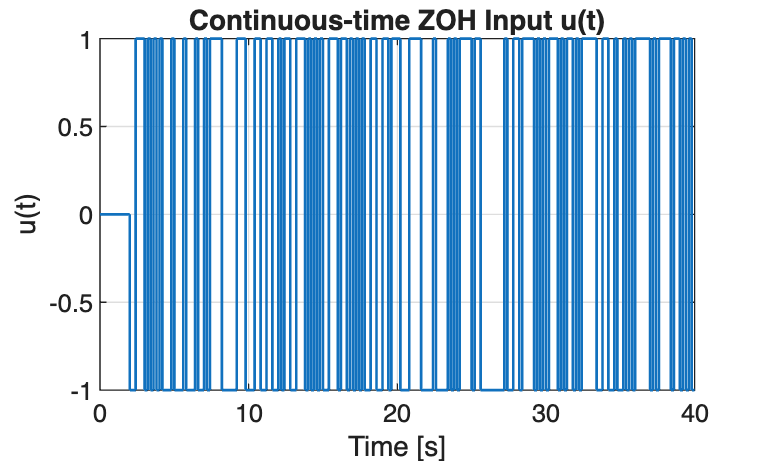


figure;
stairs(t, u_t, 'LineWidth', 1); grid on;                   %u(t) ZOH plot
xlabel('Time [s]'); ylabel('u(t)');
title('Continuous-time ZOH Input u(t)');

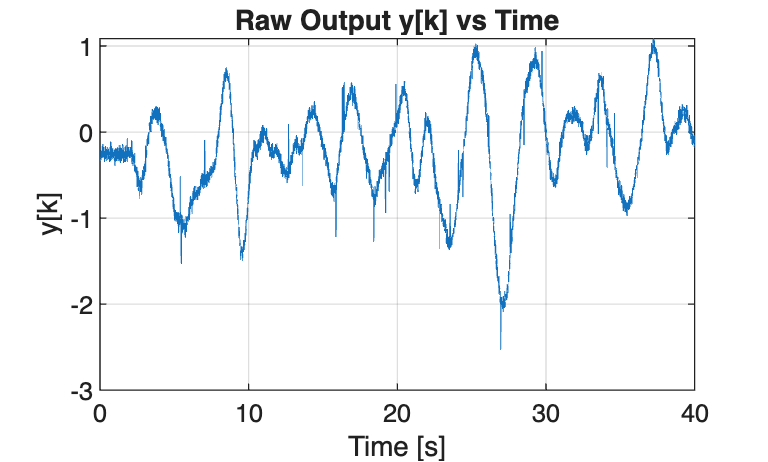


figure; 
plot(t, y_raw); grid on; xlabel('Time [s]'); ylabel('y[k]'); %raw y[k] plotting with bias, noise, spikes
title('Raw Output y[k] vs Time');

## 1.2 Data cleaning

### (a) spike

We detect spikes using the Median Absolute Deviation method,a any sample that deviates more than 4*mean_abs_dev from the median is considered a spike.

y = y_raw;
spikes = false(size(y));   
med = median(y); 
mad_val = median(abs(y - med));  

for i = (Nz+1):N                             % do not detect spikes inside the zero-input segment
    if abs(y(i) - med) > 4 * mad_val
        spikes(i) = true;
    end
end

% replace spikes by NaN (marking them for interpolation)
y(spikes) = NaN;

% linear interpolation
for i = 2:N-1
    if isnan(y(i))
        y(i) = (y(i-1) + y(i+1)) / 2;
    end
end

### (b) Bias 

bias_val = mean(y(1:Nz));                   %proper bias estimation
y = y - bias_val;
fprintf('Removed bias: %.4f\n', bias_val);

Removed bias: -0.2530


### (c) Moving average

To reduce measurement noise, we apply a moving average filter. For each sample, movmean replaces y[k] with the average of the previous M samples. We use M = 5, which smooths the noise without distorting the dynamics. The same filter is also applied to the input signal because filtered input will be used in the next problem.

M = 5;                                  % number of steps used
y_clean = movmean(y, M);                % used built-in func. instead of hardcoding
u_filter = movmean(u, M);

### Raw and Clean Plot

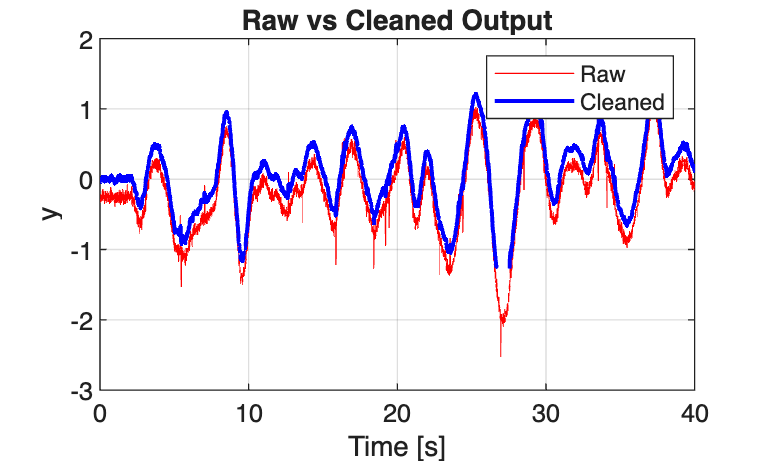

figure;
plot(t, y_raw, 'r'); hold on;
plot(t, y_clean, 'b', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('y');
legend('Raw','Cleaned');
title('Raw vs Cleaned Output');
grid on;

## ***PROBLEM 2 (25 Pts.)***

% Consequent NAN's may occure (which our hardcoded linear interpolation is not available to overcome).
% Because spike detection is hardcoded (not with the built-in MATLAB function) this minor error is inevitable. 
% Remove remaining NaNs from filtered signals, at spike interpolation (with built-in function)

u_filter = fillmissing(u_filter, 'linear');
y_clean  = fillmissing(y_clean, 'linear');

### (a) Split data into training (first 25 s) and validation (last 15 s) , estimate FIR parameters for nb = 40 and nb = 120

% Split data
train_end = round(25 / Tsampling);  % 25 seconds - 2500 sample
train_u = u_filter(1:train_end);
train_y = y_clean(1:train_end);

val_u   = u_filter(train_end+1 : end);
val_y   = y_clean(train_end+1 : end);
t_val   = t(train_end+1 : end);


%nb = 40
nb1 = 40;
Ntr = length(train_u);

Phi40 = zeros(Ntr-nb1, nb1);
y40   = zeros(Ntr-nb1, 1);

for k = nb1+1:Ntr
    for i = 1:nb1
        Phi40(k-nb1, i) = train_u(k - i);
    end
    y40(k-nb1) = train_y(k);
end

b40 = Phi40 \ y40;


%nb = 120
nb2 = 120;
Phi120 = zeros(Ntr-nb2, nb2);
y120   = zeros(Ntr-nb2, 1);

for k = nb2+1:Ntr
    for i = 1:nb2
        Phi120(k-nb2, i) = train_u(k - i);
    end
    y120(k-nb2) = train_y(k);
end

b120 = Phi120 \ y120;

### (b) Prediction on validation set

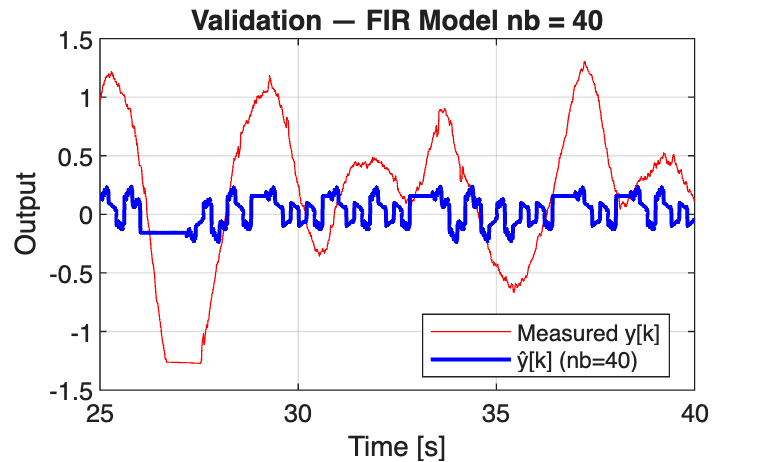

% Full length filtered input from problem 1
Nu = length(u_filter);

% Prediction nb = 40
yhat40_full = zeros(Nu,1);
for k = 1:Nu
    s = 0;
    for i = 1:nb1
        if (k-i) >= 1
            s = s + b40(i) * u_filter(k-i);
        end
    end
    yhat40_full(k) = s;
end

% Prediction nb = 120
yhat120_full = zeros(Nu,1);
for k = 1:Nu
    s = 0;
    for i = 1:nb2
        if (k-i) >= 1
            s = s + b120(i) * u_filter(k-i);
        end
    end
    yhat120_full(k) = s;
end

% Extract validation portion
yhat40  = yhat40_full(train_end+1:end);
yhat120 = yhat120_full(train_end+1:end);

% Plot nb = 40
figure;
plot(t_val, val_y, 'r'); hold on;
plot(t_val, yhat40, 'b', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('Output');
legend('Measured y[k]', 'ŷ[k] (nb=40)', 'Location', 'best');
title('Validation — FIR Model nb = 40');
grid on;

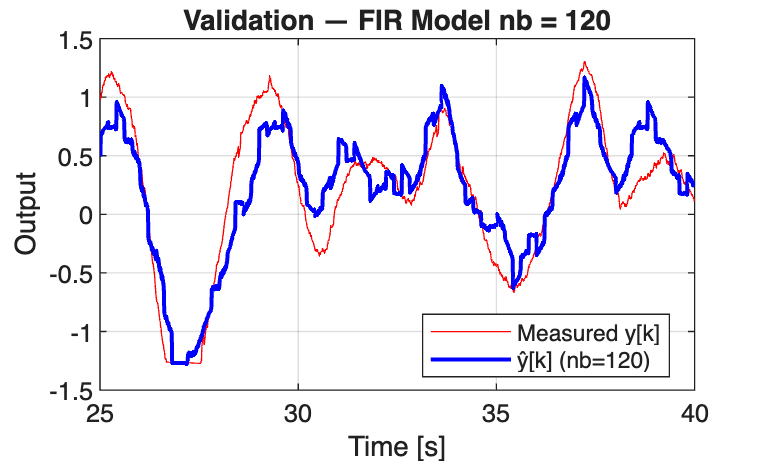


% Plot nb = 120
figure;
plot(t_val, val_y, 'r'); hold on;
plot(t_val, yhat120, 'b', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('Output');
legend('Measured y[k]', 'ŷ[k] (nb=120)', 'Location', 'best');
title('Validation — FIR Model nb = 120');
grid on;

### (c) RMSE and Fit 

rmse40  = sqrt(mean((val_y - yhat40 ).^2));
rmse120 = sqrt(mean((val_y - yhat120).^2));

fit40  = (1 - norm(val_y - yhat40 )/norm(val_y - mean(val_y))) * 100;
fit120 = (1 - norm(val_y - yhat120)/norm(val_y - mean(val_y))) * 100;

fprintf('\n VALIDATION METRICS \n');


 VALIDATION METRICS 


fprintf('nb =  40 → RMSE = %.4f, Fit = %.2f %%\n', rmse40,  fit40);

nb =  40 → RMSE = 0.6163, Fit = 3.61 %


fprintf('nb = 120 → RMSE = %.4f, Fit = %.2f %%\n', rmse120, fit120);

nb = 120 → RMSE = 0.2726, Fit = 57.37 %


## ***PROBLEM 3 (25 Pts.)***

% Using the same data from problem 2

arx_pairs = [1 40;      % Model 1: short output history, same nb as FIR for comparision
             2 40;      % Model 2: more poles, same nb
             2 80];     % Model 3: more poles and longer input history

numModels = 3

numModels = 3

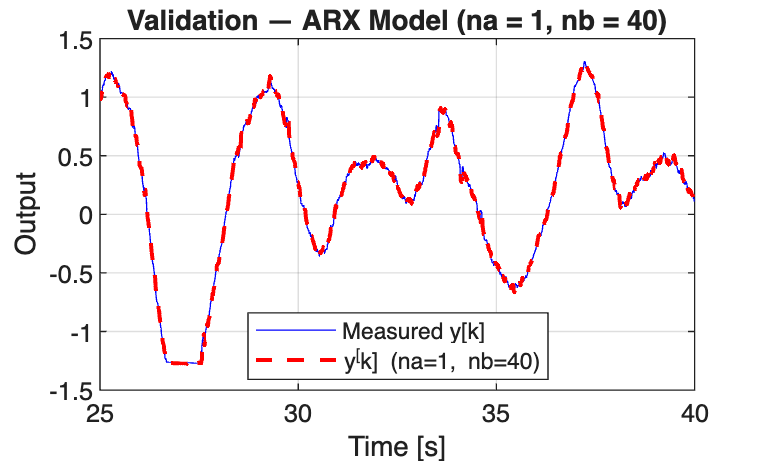

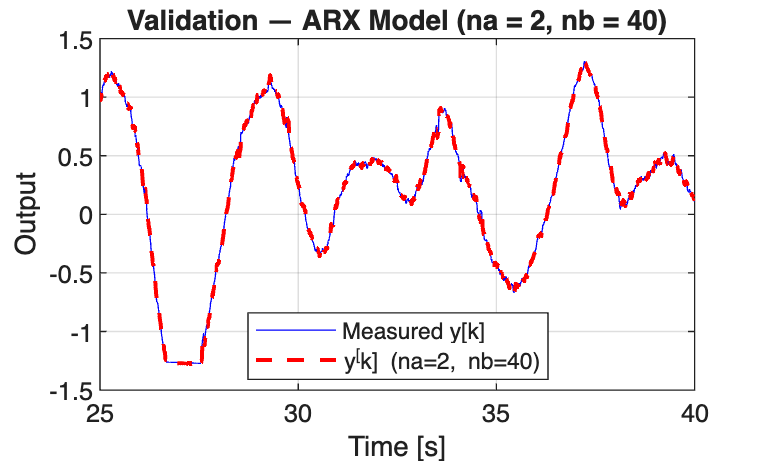

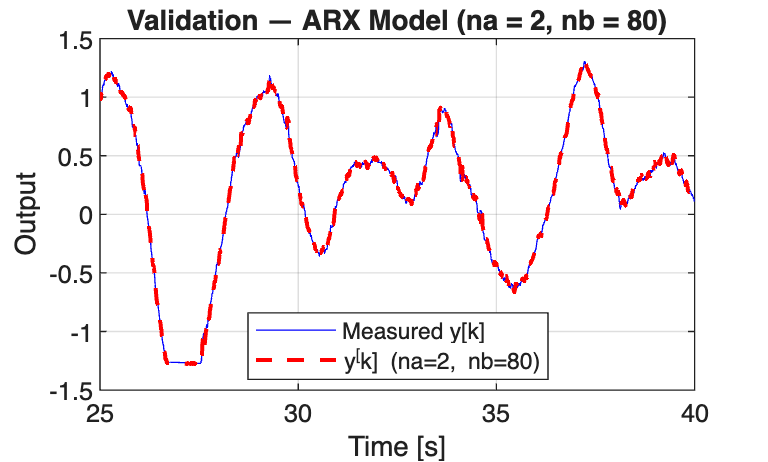

rmse_arx  = zeros(numModels, 1);
fit_arx   = zeros(numModels, 1);

Nu_total  = length(u_filter);
Ntr       = length(train_u);    % number of training samples

for m = 1:numModels
    
    na = arx_pairs(m, 1);       % number of past outputs
    nb = arx_pairs(m, 2);       % number of past inputs
    
    % First usable index computation (need at least n_a past outputs and nb past inputs)
    k0  = max(na, nb) + 1;
    Ktr = Ntr - k0 + 1;         % number of training rrows
    
    % Build regression matrix and output vector y_arx on training data
    Phi   = zeros(Ktr, na + nb);
    y_arx = zeros(Ktr, 1);
    
    for k = k0:Ntr
        % past outputs
        Phi(k-k0+1, 1:na) = -train_y(k-1:-1:k-na).';
        
        % past inputs
        Phi(k-k0+1, na+1:end) = train_u(k-1:-1:k-nb).';
        
        % current output
        y_arx(k-k0+1) = train_y(k);
    end
    
    % Least-squares estimate (theta)
    theta = Phi \ y_arx;
    a_arx = theta(1:na);
    b_arx = theta(na+1:end);
    
    % One step ahead prediction, just like in the lecture sldies
    yhat_full = zeros(Nu_total, 1);
    
    for k = k0:Nu_total
        y_past = y_clean(k-1:-1:k-na);
        u_past = u_filter(k-1:-1:k-nb);
        
        % y^[k]
        yhat_full(k) = -a_arx.' * y_past + b_arx.' * u_past;
    end
    
    % Take only validation part
    yhat_val = yhat_full(train_end+1:end);
    
    % Compute RMSE and FIT on validation data
    rmse_arx(m) = sqrt(mean((val_y - yhat_val).^2));
    fit_arx(m)  = (1 - norm(val_y - yhat_val) / norm(val_y - mean(val_y))) * 100;
    
    % plot for each na,nb pair
    figure;
    plot(t_val, val_y, 'b'); hold on;
    plot(t_val, yhat_val, 'r--', 'LineWidth', 1.5);

    xlabel('Time [s]'); ylabel('Output');
    legend('Measured y[k]', ...
           sprintf('y^[k] (na=%d, nb=%d)', na, nb), ...
           'Location', 'best');
    title(sprintf('Validation — ARX Model (na = %d, nb = %d)', na, nb));
    grid on;
    
end


% Compare models
[bestFit, bestIdx] = max(fit_arx);
best_na = arx_pairs(bestIdx, 1);
best_nb = arx_pairs(bestIdx, 2);

fprintf('\n ARX Model Comparision (validation set)\n');


 ARX Model Comparision (validation set)


for m = 1:numModels
    fprintf('(na,nb) = (%2d, %3d)   RMSE = %.4f, Fit = %.2f %%\n', ...
        arx_pairs(m,1), arx_pairs(m,2), rmse_arx(m), fit_arx(m));
end

(na,nb) = ( 1,  40)   RMSE = 0.0194, Fit = 96.97 %
(na,nb) = ( 2,  40)   RMSE = 0.0189, Fit = 97.05 %
(na,nb) = ( 2,  80)   RMSE = 0.0189, Fit = 97.05 %


fprintf('Best pair based on validation FIT: (na, nb) = (%d, %d), Fit = %.2f %%\n', ...
        best_na, best_nb, bestFit);

Best pair based on validation FIT: (na, nb) = (2, 80), Fit = 97.05 %


## ***PROBLEM 4 (25 Pts.)***

### Problem setup

% Plant dynamics: x[k+1] = 0.9 x[k] + 2 u[k],  y[k]   = x[k]
A = 0.9;
B = 2.0;
C = 1.0;
T = 0.05;                % sample time
Tf = 6;                  % simulation time
Nsim = round(Tf/T);


Np = 8;       % MPC prediction horizon
Nc = 4;       % MPC control horizon

Q = 1;        % Cost weights
R = 0.1;      % Cost weights


u_max  = 0.55; % Constraints
du_max = 0.30; % Constraints


F = zeros(Np,1); % F vector
Ap = A;
for i = 1:Np
    F(i) = C * Ap;
    Ap = Ap * A;
end

H = zeros(Np, Nc); % H matrix
for i = 1:Np
    for j = 1:Nc
        if j <= i
            Aexp = 1;
            for k = 1:(i-j)
                Aexp = Aexp * A;
            end
            H(i,j) = C * (Aexp * B);
        end
    end
end

% S matrix
S = tril(ones(Nc));

% Phi matrix
Phi = H * S;

Qbar = Q * eye(Np);
Rbar = R * eye(Nc);

options = optimoptions('quadprog','Display','off');

### (a) Design MPC, reference is step with magnitude 2

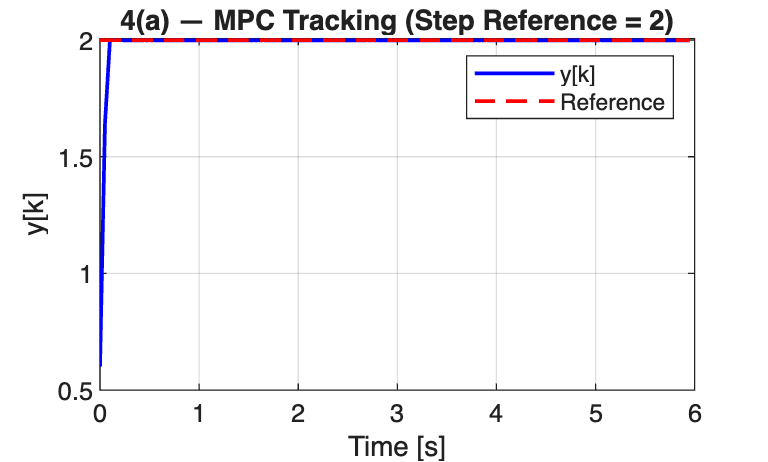

r_step = 2;

x = 0;        % state
u_prev = 0;   % previous control

% For 4(d): store first predicted output y_hat[k+1|k]
yhat_hist_a = zeros(Nsim,1);
yhat_hist_b = zeros(Nsim,1);
yhat_hist_c = zeros(Nsim,1);

u_hist_a = zeros(Nsim,1);
ref_hist_a = zeros(Nsim,1);

for k = 1:Nsim
    
    % Reference over prediction horizon
    r_vec = r_step * ones(Np,1);
    
    % b_k
    u_vec = u_prev * ones(Nc,1);
    b_k = F*x + H*u_vec;
    
    % QP
    Hqp = Phi.' * Qbar * Phi + Rbar;
    fqp = Phi.' * Qbar * (b_k - r_vec);
    
    % Constraints
    A_rate = [ eye(Nc); -eye(Nc) ];
    b_rate = [ du_max*ones(Nc,1); du_max*ones(Nc,1) ];
    
    A_u = [ S; -S ];
    b_u = [ u_max*ones(Nc,1) - u_vec;
            u_max*ones(Nc,1) + u_vec ];
    
    Aineq = [A_rate; A_u];
    bineq = [b_rate; b_u];
    
    % Solve
    dU = quadprog(Hqp, fqp, Aineq, bineq, [], [], [], [], [], options);
    
    % Predicted output horizon for case (a)
    Ypred_a = b_k + Phi*dU;
    yhat_hist_a(k) = Ypred_a(1);     % one–step ahead prediction

    du = dU(1);
    u = u_prev + du;
    
    % Plant update
    x = A*x + B*u;
    y = x;
    
    % Log
    y_hist_a(k) = y;
    u_hist_a(k) = u;
    ref_hist_a(k) = r_step;
    
    u_prev = u;
end

t_mpc = (0:Nsim-1)*T;

figure; 
plot(t_mpc, y_hist_a,'b','LineWidth',1.4); hold on;
plot(t_mpc, ref_hist_a,'r--','LineWidth',1.4);
xlabel('Time [s]'); ylabel('y[k]');
title('4(a) — MPC Tracking (Step Reference = 2)');
legend('y[k]','Reference'); grid on;

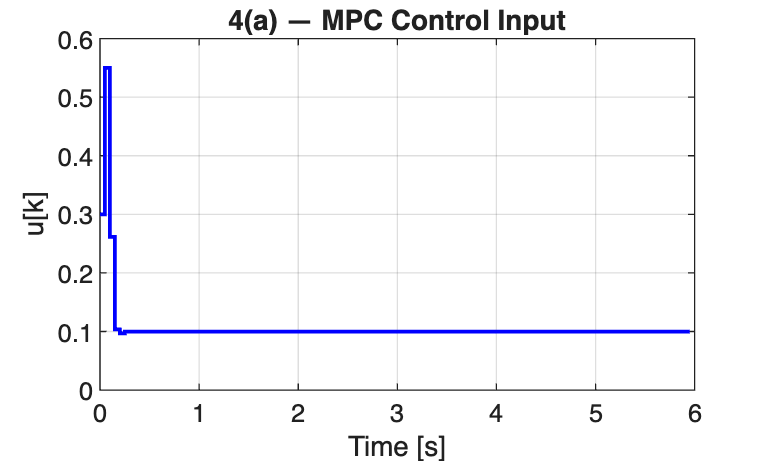


figure;
stairs(t_mpc, u_hist_a,'b','LineWidth',1.4);
xlabel('Time [s]'); ylabel('u[k]');
title('4(a) — MPC Control Input');
grid on;

### (b) Part a controller with measurement noise

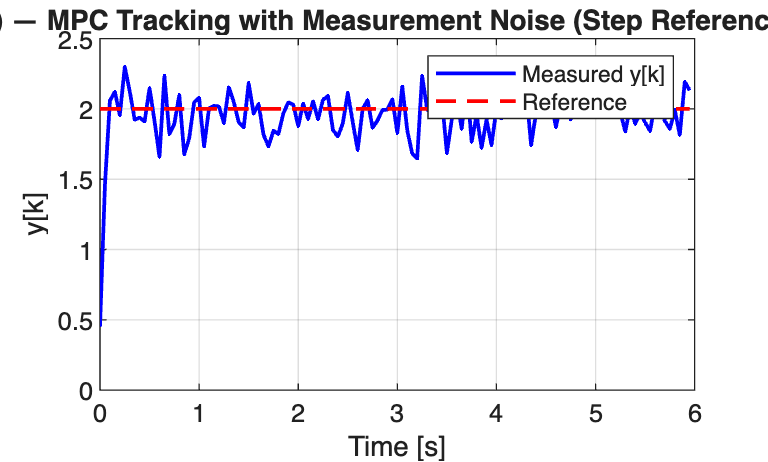

noise_amp = 0.15;   % Visible amplitude

x = 0;
u_prev = 0;

y_hist_b = zeros(Nsim,1);
u_hist_b = zeros(Nsim,1);
ref_hist_b = zeros(Nsim,1);

for k = 1:Nsim

    r_vec = r_step * ones(Np,1);

    u_vec = u_prev * ones(Nc,1);
    b_k = F*x + H*u_vec;

    Hqp = Phi.'*Qbar*Phi + Rbar;
    fqp = Phi.'*Qbar*(b_k - r_vec);

    A_rate = [ eye(Nc); -eye(Nc) ];
    b_rate = [ du_max*ones(Nc,1); du_max*ones(Nc,1) ];

    A_u = [ S; -S ];
    b_u = [ u_max*ones(Nc,1) - u_vec;
            u_max*ones(Nc,1) + u_vec ];

    Aineq = [A_rate; A_u];
    bineq = [b_rate; b_u];

    dU = quadprog(Hqp, fqp, Aineq, bineq, [], [], [], [], [], options);

    % Predicted output horizon for case (b)
    Ypred_b = b_k + Phi*dU;
    yhat_hist_b(k) = Ypred_b(1);


    du = dU(1);
    u = u_prev + du;

    % True plant
    x_true = A*x + B*u;

    % Measurement
    y_meas = x_true + noise_amp*randn;

    % The controller uses y_meas as state estimate
    x = y_meas;

    y_hist_b(k) = y_meas;
    u_hist_b(k) = u;
    ref_hist_b(k) = r_step;

    u_prev = u;
end

figure; 
plot(t_mpc, y_hist_b,'b','LineWidth',1.4); hold on;
plot(t_mpc, ref_hist_b,'r--','LineWidth',1.4);
xlabel('Time [s]'); ylabel('y[k]');
title('4(b) — MPC Tracking with Measurement Noise (Step Reference = 2)');
legend('Measured y[k]','Reference'); grid on;

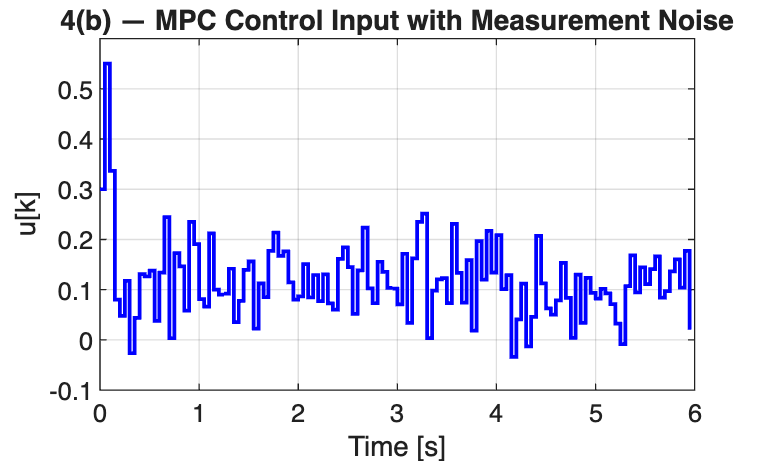


figure;
stairs(t_mpc, u_hist_b,'b','LineWidth',1.4);
xlabel('Time [s]'); ylabel('u[k]');
title('4(b) — MPC Control Input with Measurement Noise');
grid on;

###  (c) Same construct at part b but reference is a sine wave r[k] = sin(0.1*pi/3 * k)

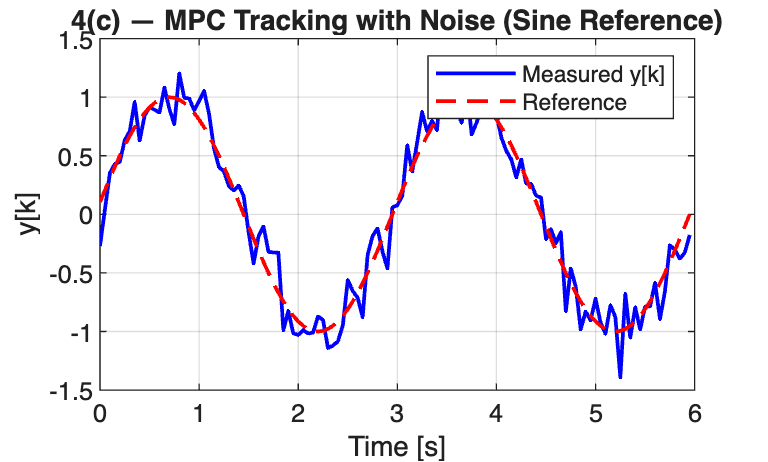

x = 0;
u_prev = 0;

y_hist_c = zeros(Nsim,1);
u_hist_c = zeros(Nsim,1);
ref_hist_c = zeros(Nsim,1);

for k = 1:Nsim
    
    % Sine reference Np steps ahead
    ref_horizon = sin( (0.1*pi/3) * (k : k+Np-1) ).';
    
    u_vec = u_prev * ones(Nc,1);
    b_k = F*x + H*u_vec;

    Hqp = Phi.'*Qbar*Phi + Rbar;
    fqp = Phi.'*Qbar*(b_k - ref_horizon);

    A_rate = [ eye(Nc); -eye(Nc) ];
    b_rate = [ du_max*ones(Nc,1); du_max*ones(Nc,1) ];

    A_u = [ S; -S ];
    b_u = [ u_max*ones(Nc,1) - u_vec;
            u_max*ones(Nc,1) + u_vec ];

    Aineq = [A_rate; A_u];
    bineq = [b_rate; b_u];

    dU = quadprog(Hqp, fqp, Aineq, bineq, [], [], [], [], [], options);
    
    % Predicted output horizon for case (c)
    Ypred_c = b_k + Phi*dU;
    yhat_hist_c(k) = Ypred_c(1);

    du = dU(1);
    u = u_prev + du;

    x_true = A*x + B*u;
    y_meas = x_true + noise_amp*randn;

    x = y_meas;

    y_hist_c(k) = y_meas;
    u_hist_c(k) = u;
    ref_hist_c(k) = ref_horizon(1);

    u_prev = u;
end

figure; 
plot(t_mpc, y_hist_c,'b','LineWidth',1.4); hold on;
plot(t_mpc, ref_hist_c,'r--','LineWidth',1.4);
xlabel('Time [s]'); ylabel('y[k]');
title('4(c) — MPC Tracking with Noise (Sine Reference)');
legend('Measured y[k]','Reference'); grid on;

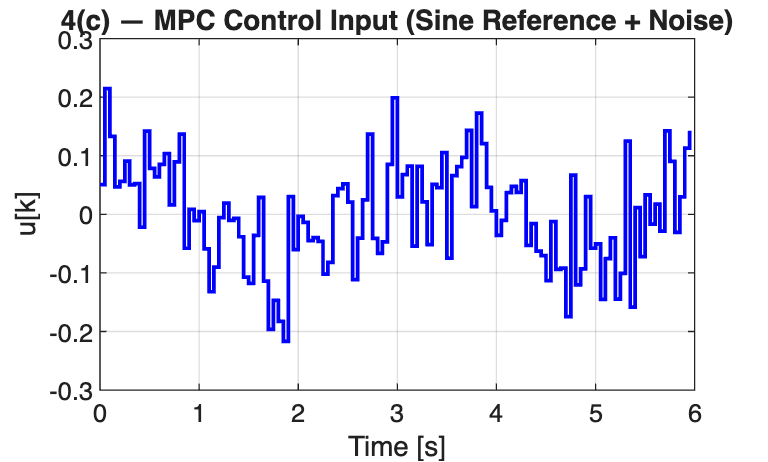


figure;
stairs(t_mpc, u_hist_c,'b','LineWidth',1.4);
xlabel('Time [s]'); ylabel('u[k]');
title('4(c) — MPC Control Input (Sine Reference + Noise)');
grid on;

### (d) Reference tracking vs predicted output

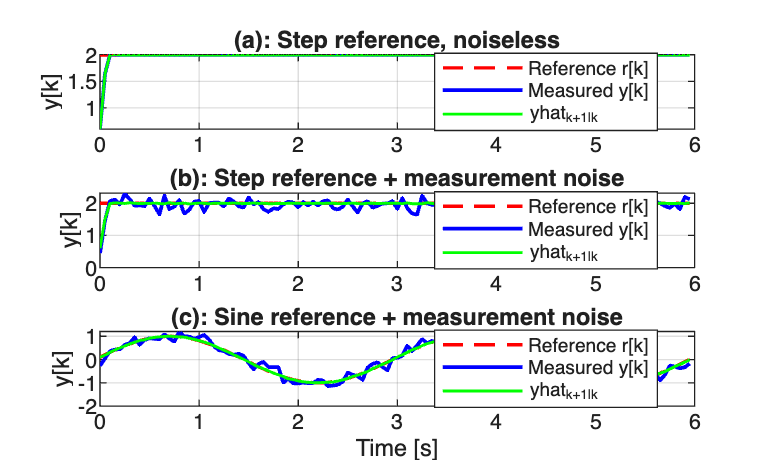

figure;

subplot(3,1,1);
plot(t_mpc, ref_hist_a, 'r--', 'LineWidth', 1.3); hold on;
plot(t_mpc, y_hist_a,   'b',   'LineWidth', 1.4);
plot(t_mpc, yhat_hist_a,'g',   'LineWidth', 1.1);
grid on;
title('(a): Step reference, noiseless');
ylabel('y[k]');
legend('Reference r[k]', 'Measured y[k]', 'yhat_{k+1|k}', 'Location', 'best');

subplot(3,1,2);
plot(t_mpc, ref_hist_b, 'r--', 'LineWidth', 1.3); hold on;
plot(t_mpc, y_hist_b,   'b',   'LineWidth', 1.4);
plot(t_mpc, yhat_hist_b,'g',   'LineWidth', 1.1);
grid on;
title('(b): Step reference + measurement noise');
ylabel('y[k]');
legend('Reference r[k]', 'Measured y[k]', 'yhat_{k+1|k}', 'Location', 'best');

subplot(3,1,3);
plot(t_mpc, ref_hist_c, 'r--', 'LineWidth', 1.3); hold on;
plot(t_mpc, y_hist_c,   'b',   'LineWidth', 1.4);
plot(t_mpc, yhat_hist_c,'g',   'LineWidth', 1.1);
grid on;
title('(c): Sine reference + measurement noise');
xlabel('Time [s]');
ylabel('y[k]');
legend('Reference r[k]', 'Measured y[k]', 'yhat_{k+1|k}', 'Location', 'best');